# Properties for Composites with Distributed Orientation

When a discontinuous fiber composite had a distribution of fiber orientation, the properties are calculated using a two-step homogenization process.  As shown in the figure below, the composite is first decomposed into pseudo-grains.  Each pseudo-grain has the same fiber volume fraction as the overall composite, but has unidirectional orientation.  

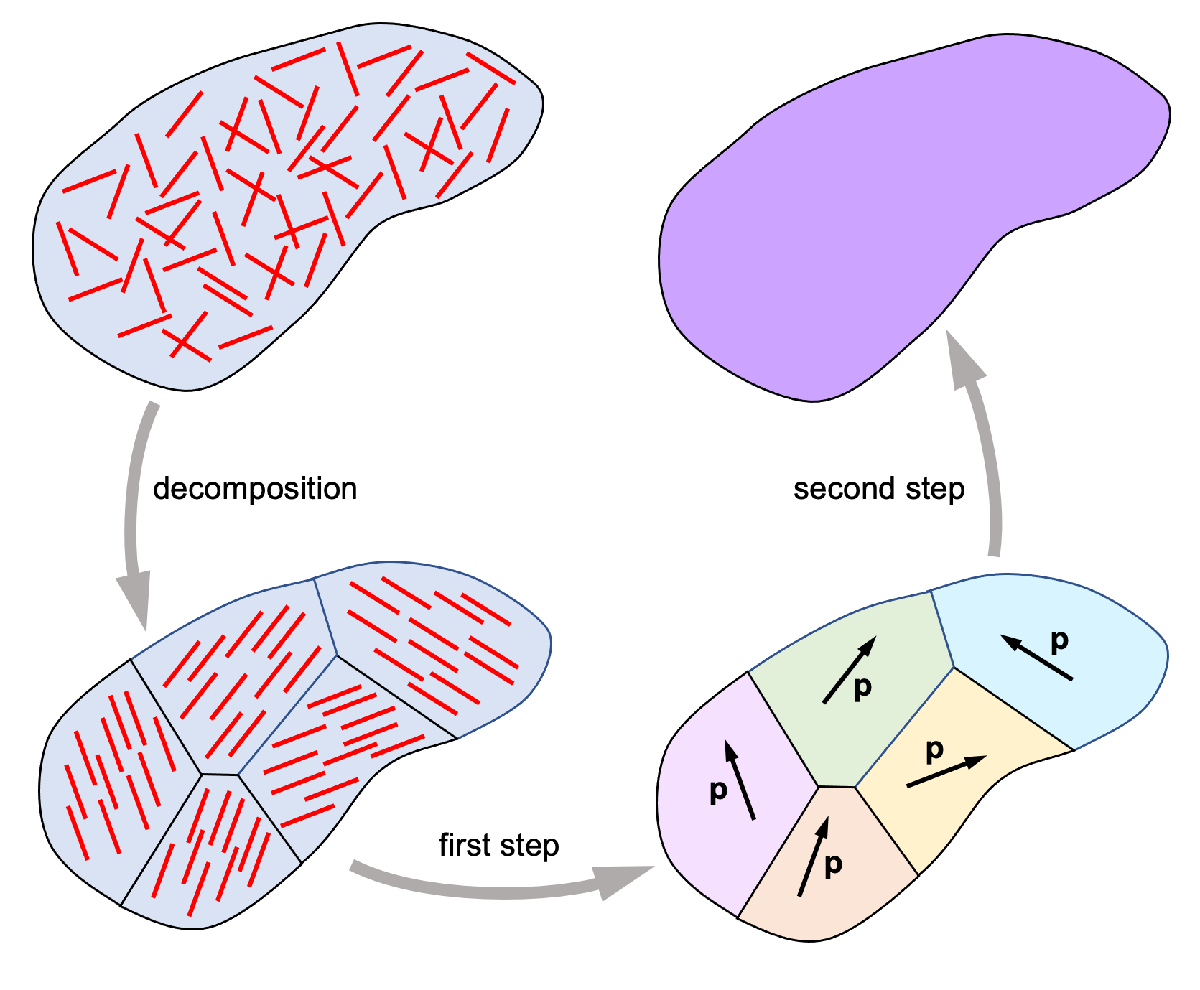

In the first homogenization step, the effective stiffness $\mathbb{C}^p$ of each pseudo-grain is calculated.  If thermal expansion is being calculated, one also determines a ther stress tensor $\mathbf{\beta}^p$ for each pseudo-grain.  For linear elastic behavior, the pseudo-grain properties differ only by a coordinate rotation, so the properties can be calculated in one reference orientation $\mathbf{p}$.  The live script `UnidirectionalProperties.mlx` shows how this is done and compares a few different models for this step.

In the second step, the pseudo-grain properties are homogenized to find the overall composite stiffness $\mathbb{C}$ and thermal stress tensor $\mathbf{\beta}$.  This is the step explained here.  

As a demonstration, we'll reproduce the plot of stiffness vs. orientation in Fig. 8.5(a), and use the same properties to create a thermal expansion plot similar to Fig. 8.8(a).  The composite is glass fiber/polypropylene with 40% by weight of glass fibers and fiber aspect ratio $\ell / d_f$ = 100, and constituent properties are given in Table 8.2.  The orientation states will all be transversely isotropic, and will range from random-in-plane to isotropic to fully aligned.  The 1 direction will be the axis of symmetry, so the properties are isotropic in the 2-3 plane.  

First, we'll enter the properties of the constituent materials and calculate the pseudo-grain properties.  Here we use the Mori-Tanaka model.  

% Input materials properties
Ef      =  73;      % Fiber modulus, GPa   
nuf     =   0.21;   % Fiber Poisson ratio
rhof    =   2.55;   % Fiber density, g/cm^3
alphaf  =   4.9;    % Fiber thermal expansion, 1e-6/K
Em      =   1.325;  % Matrix modulus, GPa
num     =   0.42;   % Matrix Poisson ratio
rhom    =   0.92;   % Matrix density, g/cm^3
alpham  = 140;      % Fiber thermal expansion, 1e-6/K
wf      =   0.40;   % Fiber weight fraction
% Calculate fiber volume fraction
vf      = weightFrac2volFrac(wf, rhof, rhom);
fprintf('The fiber volume fraction is %5.3f\n', vf)

The fiber volume fraction is 0.194


aspect  = 100;      % Fiber aspect ratio, l/d

% Pseudo-grain properties, unidirectional orientation
[Cp, betap] = mori(iso2C(Ef, nuf), iso2C(Em, num), ...
                   vf, aspect, alphaf, alpham);

The utility function `weightFrac2volFrac` has been used to convert weight fraction of fibers to volume fraction.  This is a simple calculation (assuming that only two phases are present), but convenient.

The first two arguments to `mori` are $\mathbb{C}^f$ and $\mathbb{C}^m$, the stiffness tensors of the fiber and matrix.  Here we've used the `iso2C` function to calculate those tensors from the Young's modulus and Poisson ratio of each material.  

Now we'll vary the orientation by adjusting $\lambda_1$, the eigenvalue of $\mathbf{A}$ in the material symmetry direction, and calculate the properties for each orientation state.  The functions `oravg4` and `oravg2` do this for the stiffness tensor and the thermal stress tensor, respectively.  We are using a Voigt average here (see Sections 8.4.2 and 8.6.3), so the composite properties are $\mathbb{C} = \left \langle \mathbb{C}^p \right \rangle$ and $\mathbf{\beta} = \left \langle \mathbf{\beta}^p \right \rangle$.  

Averaging a fourth-order tensor like $\mathbb{C}$ requires the fourth-order orientation tensor, and we'll use the natural closure here to get that from the second-order tensor.  Here's the calculation. 

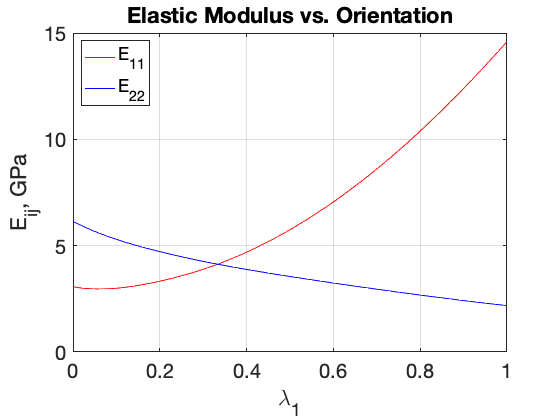

closure = 'N';            % Natural closure approximation
R4 = diag([1,1,1,2,2,2]); % Used for tensor products

% Cycle through a range of orientation states
lambda1 = linspace(0, 1, 101);  % Orientation eigenvalue
E11     = zeros(size(lambda1)); % Store modulus values
E22     = zeros(size(lambda1));
alpha11 = zeros(size(lambda1)); % Store thermal expansion
alpha22 = zeros(size(lambda1)); 

for i = 1:length(lambda1)  % Loop over orientation states
    % Orientation tensor for this value of lambda1
    A = diag([lambda1(i), (1-lambda1(i))/2, (1-lambda1(i))/2]);
    % Averaged stiffness tensor
    C = oravg4(Cp, closeA4(A, closure));
    EngCon = C2eng(C);   % Engineering constants
    E11(i) = EngCon(1);  % Store E11 value
    E22(i) = EngCon(2);  % Store E22 value
    % Averaged thermal stress tensor, 6x1 form
    beta = oravg2(betap, A);
    % Averaged thermal expansion tensor, 6x1 form
    alpha = inv4(C) * R4 * beta;
    alpha11(i) = alpha(1);  % Store alpha11
    alpha22(i) = alpha(2);  % Store alpha22
end

% Plot the elastic modulus vs. orientation
figure
plot(lambda1, E11, 'r-', lambda1, E22, 'b-')
set(gca, 'FontSize', 20)
axis([0 1 0 15])
xlabel('\lambda_1')
ylabel('E_{ij}, GPa')
legend('E_{11}', 'E_{22}', 'Location', 'NorthWest')
grid on
title('Elastic Modulus vs. Orientation')

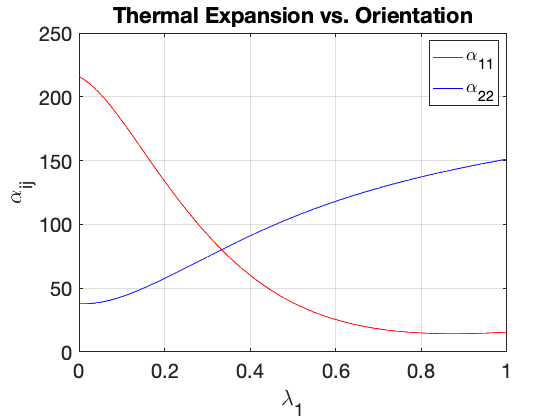


% Plot thermal expansion vs. orientation
figure
plot(lambda1, alpha11, 'r-', lambda1, alpha22, 'b-')
set(gca, 'FontSize', 20)
axis([0 1 0 250])
xlabel('\lambda_1')
ylabel('\alpha_{ij}')
legend('\alpha_{11}', '\alpha_{22}', 'Location', 'NorthEast')
grid on
title('Thermal Expansion vs. Orientation')

Looking at the results, $\lambda_1$ = 1 is unidirectional orientation in the 1 direction, and we see that $E_{11}$ has its maximum value, while $E_{22}$ is at its minimum.  Similarly, $\alpha_{11}$ is at its minimum and $\alpha_{22}$ is maximum in this state.

As $\lambda_1$ decreases, the fibers are less aligned in the 1 direction, so $E_{11}$ decreases and $E_{22}$ increases, and $\alpha_{11}$ increases while $\alpha_{22}$ decreases.

When $\lambda_1$ = 1/3 the orientation is isotropic (3-D random), the properties are the same in all directions, and the red and blue curves intersect in both plots. 

The value $\lambda_1$ = 0 represents random orientation in the 2-3 plane.  Now $E_{22}$ is larger than $E_{11$, while $\alpha_{22}$ is less than $\alpha_{11}$.  In this orientation state, $\alpha_{11}$, which is the out-of-plane expansion coefficient, is substantially larger than the matrix expansion coefficient.  This occurs because the matrix tries to expand volumetrically, but its in-plane expansion is constrained by the fibers so its out-of-plane expansion is greater than for the matrix alone.  